# Create and Train a Linear Layer

This example shows how to create and train a linear layer.

Create a linear layer and train it on a simple time series problem.

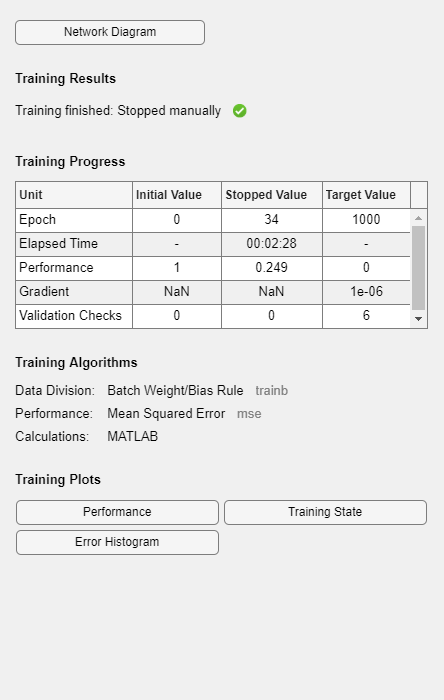

x = {0 -1 1 1 0 -1 1 0 0 1};
t = {0 -1 0 2 1 -1 0 1 0 1};
net = linearlayer(1:2,0.01);
[Xs,Xi,Ai,Ts] = preparets(net,x,t);
net = train(net,Xs,Ts,Xi,Ai);

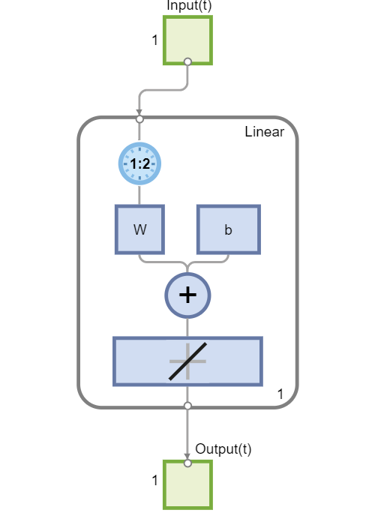

view(net)

Y = net(Xs,Xi);
perf = perform(net,Ts,Y)

perf = 0.2486

*Copyright 2010 The MathWorks, Inc.*